clc
clear
close all

parameters

m_c=1.5 

m_c = 1.5000

m_p=0.5

m_p = 0.5000

g=9.82

g = 9.8200

L=1

L = 1

d_1=0.01

d_1 = 0.0100

d_2=0.01

d_2 = 0.0100

system

A=[0,0,1,0;0,0,0,1;0,g*m_p/m_c,-d_1/m_c,-d_2/(L*m_c);0,g*(m_p+m_c)/(L*m_c),-d_1/(L*m_c),-d_2*(m_c+m_p)/(L*L*m_c*m_p)]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067   -0.0267



B=[0;0;1/m_c;1/(L*m_c)]

B =          0
         0
    0.6667
    0.6667



C1 = [0 1 0 0]

C1 =      0     1     0     0


C2 = [1 0 0 0]

C2 =      1     0     0     0



D=0

D = 0


sys1 = ss(A,B,C1,D)

sys1 =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys2 = ss(A,B,C2,D)

sys2 =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



controllability and observability

l = rank(ctrb(sys1)) %If rank(i) is 4 then the system is controllable.

l = 4

m = rank(obsv(sys1)) %If rank(j) is 4 then system is observable.

m = 3

n = rank(ctrb(sys2))

n = 4

o = rank(obsv(sys2))

o = 4

x0 = [0; 5*pi/180; 0; 0]

x0 =          0
    0.0873
         0
         0


des_pole = [-3;-3;-3;-3]

des_pole =     -3
    -3
    -3
    -3


K = acker(A,B,des_pole)

K =   -12.3727  113.3432  -16.5321   34.4821


A1 = A-B*K

A1 =          0         0    1.0000         0
         0         0         0    1.0000
    8.2485  -72.2888   11.0148  -22.9948
    8.2485  -62.4688   11.0148  -23.0148


`closed loop system using state feedback control K `

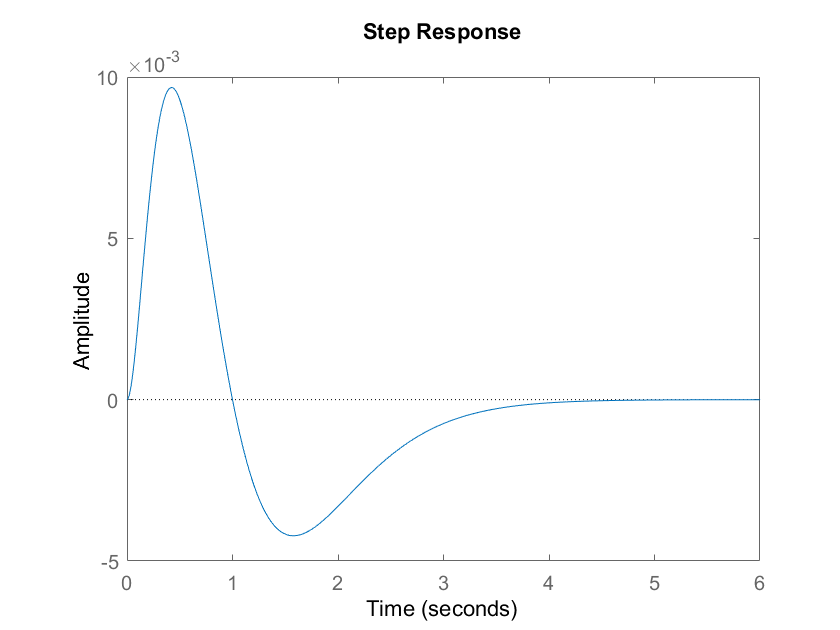

sys3=ss(A1,B,C1,D);
step(sys3)

[r,s]=ss2tf(A1,B,C1,D)

r =          0         0    0.6667    0.0000    0.0000


s =     1.0000   12.0000   54.0000  108.0000   81.0000


h=tf(r,s)

h =
 
  0.6667 s^2 + 1.687e-15 s + 1.984e-15
  ------------------------------------
   s^4 + 12 s^3 + 54 s^2 + 108 s + 81
 
Continuous-time transfer function.



zero(h)

ans = 	1.0e+-7 *

  -0.0000 + 0.5456i
  -0.0000 - 0.5456i


des_eig = [-1.5; -2.5; -4.0; -10.5]

des_eig =    -1.5000
   -2.5000
   -4.0000
  -10.5000


k = place(A,B,des_eig)

k =   -24.0580  200.0034  -34.0267   61.7267


pole(sys3)

ans =   -3.0008 + 0.0000i
  -3.0000 + 0.0008i
  -3.0000 - 0.0008i
  -2.9992 + 0.0000i


`CONTROLLER USING LQR`

C=[C2;C1]

C =      1     0     0     0
     0     1     0     0


Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R = 1;
K_lqr = lqr(A,B,Q,R)

K_lqr =    -1.0000   53.4590   -2.8185   15.3864



Ac = [(A-B*K_lqr)]

Ac =          0         0    1.0000         0
         0         0         0    1.0000
    0.6667  -32.3660    1.8724  -10.2643
    0.6667  -22.5460    1.8724  -10.2843


Bc = [B]

Bc =          0
         0
    0.6667
    0.6667


Cc = [C]

Cc =      1     0     0     0
     0     1     0     0


Dc = [D]

Dc = 0


sys4=ss(Ac,Bc,C1,D)

sys4 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  0.6667  -32.37   1.872  -10.26
   x4  0.6667  -22.55   1.872  -10.28
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pole(sys4)

ans =   -3.9804 + 0.0000i
  -3.3127 + 0.0000i
  -0.5594 + 0.4284i
  -0.5594 - 0.4284i


[num,den]=ss2tf(Ac,Bc,C1,D)

num =          0         0    0.6667    0.0000    0.0000


den =     1.0000    8.4119   21.8419   18.3732    6.5467


g=tf(num,den)

g =
 
      0.6667 s^2 + 2.309e-16 s + 1.153e-15
  ---------------------------------------------
  s^4 + 8.412 s^3 + 21.84 s^2 + 18.37 s + 6.547
 
Continuous-time transfer function.

